# NR PDSCH Throughput

This reference simulation shows how to measure the physical downlink shared channel (PDSCH) throughput of a 5G New Radio (NR) link, as defined by the 3GPP NR standard. The example implements the PDSCH and downlink shared channel (DL-SCH). The transmitter model includes PDSCH demodulation reference signals (DM-RS) and PDSCH phase tracking reference signals (PT-RS). The example supports both clustered delay line (CDL) and tapped delay line (TDL) propagation channels. You can perform perfect or practical synchronization and channel estimation. To reduce the total simulation time, you can execute the SNR points in the SNR loop in parallel by using the Parallel Computing Toolbox™.

## Introduction

This example measures the PDSCH throughput of a 5G link, as defined by the 3GPP NR standard [ [1](about:blank<#13%3E) ], [ [2](about:blank<#13%3E) ], [ [3](about:blank<#13%3E) ], [ [4](about:blank<#13%3E) ].

The example models these 5G NR features:

- DL-SCH transport channel coding

- Multiple codewords, dependent on the number of layers

- PDSCH, PDSCH DM-RS, and PDSCH PT-RS generation

- Variable subcarrier spacing and frame numerologies (2^n * 15 kHz)

- Normal and extended cyclic prefix

- TDL and CDL propagation channel models

Other features of the simulation are:

- PDSCH subband precoding using SVD

- CP-OFDM modulation

- Slot wise and non slot wise PDSCH and DM-RS mapping

- Perfect or practical synchronization and channel estimation

- HARQ operation with 16 processes

- The example uses a single bandwidth part across the whole carrier

The figure shows the implemented processing chain. For clarity, the DM-RS and PT-RS generation are omitted.

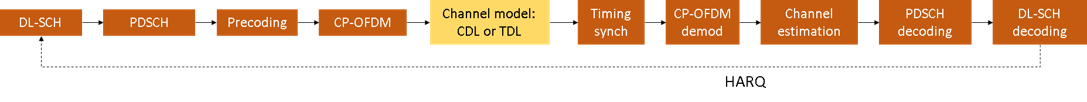

For a more detailed explanation of the steps implemented in this example, see [Model 5G NR Communication Links](docid:5g_gs#mw_b41487f2-4e53-412e-83ff-b77bd3984819) and [DL-SCH and PDSCH Transmit and Receive Processing Chain](docid:5g_gs#mw_5441cb0f-86ed-4038-8735-d0a50ea68f60).

This example supports both wideband and subband precoding. The precoding matrix is determined using SVD by averaging the channel estimate across all PDSCH PRBs in the allocation (wideband case) or in the subband.

To reduce the total simulation time, you can use the Parallel Computing Toolbox to execute the SNR points of the SNR loop in parallel.

## Simulation Length and SNR Points

Set the length of the simulation in terms of the number of 10ms frames. A large number of NFrames should be used to produce meaningful throughput results. Set the SNR points to simulate. The SNR for each layer is defined per RE, and it includes the effect of signal and noise across all antennas. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters
simParameters.NFrames = 2;      % Number of 10 ms frames
simParameters.SNRIn = [-5 0 5]; % SNR range (dB)

## Channel Estimator Configuration

The logical variable `PerfectChannelEstimator` controls channel estimation and synchronization behavior. When set to `true`, perfect channel estimation and synchronization is used. Otherwise, practical channel estimation and synchronization is used, based on the values of the received PDSCH DM-RS.

simParameters.PerfectChannelEstimator = true;

## Simulation Diagnostics

The variable `DisplaySimulationInformation` controls the display of simulation information such as the HARQ process ID used for each subframe. In case of CRC error, the value of the index to the RV sequence is also displayed.

simParameters.DisplaySimulationInformation = true;

The `DisplayDiagnostics` flag enables the plotting of the EVM per layer. This plot monitors the quality of the received signal after equalization. The EVM per layer figure shows:

- The EVM per layer per slot, which shows the EVM evolving with time.

- The EVM per layer per resource block, which shows the EVM in frequency.

This figure evolves with the simulation and is updated with each slot. Typically, low SNR or channel fades can result in decreased signal quality (high EVM). The channel affects each layer differently, therefore, the EVM values may differ across layers.

In some cases, some layers can have a much higher EVM than others. These low-quality layers can result in CRC errors. This behavior may be caused by low SNR or by using too many layers for the channel conditions. You can avoid this situation by a combination of higher SNR, lower number of layers, higher number of antennas, and more robust transmission (lower modulation scheme and target code rate).

simParameters.DisplayDiagnostics = false;

## Carrier and PDSCH Configuration

Set the key parameters of the simulation. These include:

- The bandwidth in resource blocks (12 subcarriers per resource block).

- Subcarrier spacing: 15, 30, 60, 120 (kHz)

- Cyclic prefix length: normal or extended

- Cell ID

- Number of transmit and receive antennas

A substructure containing the DL-SCH and PDSCH parameters is also specified. This includes:

- Target code rate

- Allocated resource blocks (PRBSet)

- Modulation scheme: 'QPSK', '16QAM', '64QAM', '256QAM'

- Number of layers

- PDSCH mapping type

- DM-RS configuration parameters

- PT-RS configuration parameters

Other simulation wide parameters are:

- Propagation channel model delay profile (TDL or CDL)

numWhales = 10; % For example, initialize 10 whales
whalePopulation = initializewhale(numWhales);
% Define parameter ranges
NSizeGridRange = [50, 106]; % Example range for 20 MHz bandwidth
SubcarrierSpacingRange = [15, 30, 60, 120, 240]; % Include all valid subcarrier spacing values

DelaySpreadRange = [50e-9, 500e-9]; % DelaySpread in seconds
MaximumDopplerShiftRange = [0, 30]; % MaximumDopplerShift in Hz
a = 2;
maxIterations = 10;
whaleProcessingTimes = zeros(1, numWhales); % Total processing time for each whale
% Combine ranges into a single matrix
paramRanges = {NSizeGridRange, SubcarrierSpacingRange, DelaySpreadRange, MaximumDopplerShiftRange};
averageProcessingTimePerIteration = zeros(1, maxIterations); % To store average latency after each iteration
timestamps = datetime(zeros(1, maxIterations), 'ConvertFrom', 'datenum'); % To store timestamp
for iter = 1:maxIterations
  % Update a linearly from 2 to 0
  a = 2 - iter * (2 / maxIterations);

  % Generate a random value for a2 between -1 and 1
  a2 = -1 + 2 * rand();
  for whaleIdx = 1:numWhales
    totalProcessingTime = 0;
    
    % Set waveform type and PDSCH numerology (SCS and CP type)
    simParameters.Carrier = nrCarrierConfig;         % Carrier resource grid configuration
    simParameters.Carrier.NSizeGrid = round(whalePopulation(whaleIdx, 1));           % Bandwidth in number of resource blocks (51 RBs at 30 kHz SCS for 20 MHz BW)
    simParameters.Carrier.SubcarrierSpacing = whalePopulation(whaleIdx, 2);  % 15, 30, 60, 120 (kHz)
    % Define total OFDM symbol durations including 'Normal' CP for different subcarrier spacings
    totalSymbolDurations = containers.Map({15, 30, 60, 120}, [66.67e-6, 33.33e-6, 16.67e-6, 8.33e-6]); % Example values in seconds

    % Calculate total OFDM symbol duration based on subcarrier spacing
    if isKey(totalSymbolDurations, simParameters.Carrier.SubcarrierSpacing)
        T_symbol_total = totalSymbolDurations(simParameters.Carrier.SubcarrierSpacing);
    else
        error('Unsupported subcarrier spacing for total OFDM symbol duration');
    end
    simParameters.Carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
  
   
    simParameters.Carrier.NCellID = 1;               % Cell identity
    
    % PDSCH/DL-SCH parameters
    simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
    simParameters.PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH
    
    % Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
    simParameters.PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;                 % PDSCH PRB allocation
    simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
    simParameters.PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
    
    % Scrambling identifiers
    simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
    simParameters.PDSCH.RNTI = 1;
    
    % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
    simParameters.PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
    simParameters.PDSCH.VRBBundleSize = 4;
    
    % Define the number of transmission layers to be used
    simParameters.PDSCH.NumLayers = 1;           % Number of PDSCH transmission layers
    
    % Define codeword modulation and target coding rate
    % The number of codewords is directly dependent on the number of layers so ensure that
    % layers are set first before getting the codeword number
    if simParameters.PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
        simParameters.PDSCH.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
    else
        simParameters.PDSCH.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
    end
    
    % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
    simParameters.PDSCH.DMRS.DMRSPortSet = 0:simParameters.PDSCH.NumLayers-1; % DM-RS ports to use for the layers
    simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
    simParameters.PDSCH.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
    simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
    simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
    simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
    simParameters.PDSCH.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
    simParameters.PDSCH.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)
    
    % PT-RS configuration (TS 38.211 Section 7.4.1.2)
    simParameters.PDSCH.EnablePTRS = 0;                  % Enable or disable PT-RS (1 or 0)
    simParameters.PDSCH.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
    simParameters.PDSCH.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
    simParameters.PDSCH.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
    simParameters.PDSCH.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number
    
    % Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
    simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
    simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
    simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources
    
    % Additional simulation and DL-SCH related parameters
    %
    % PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
    simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
    %
    % HARQ process and rate matching/TBS parameters
    simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
    simParameters.PDSCHExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
    simParameters.PDSCHExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]
    
    % LDPC decoder parameters
    % Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
    simParameters.PDSCHExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
    simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;
    
    % Define the overall transmission antenna geometry at end-points
    % If using a CDL propagation channel then the integer number of antenna elements is
    % turned into an antenna panel configured when the channel model object is created
    simParameters.NTxAnts = 8;                        % Number of PDSCH transmission antennas (1,2,4,8,16,32,64,128,256,512,1024) >= NumLayers
    if simParameters.PDSCH.NumCodewords > 1           % Multi-codeword transmission
        simParameters.NRxAnts = 8;                    % Number of UE receive antennas (even number >= NumLayers)
    else
        simParameters.NRxAnts = 2;                    % Number of UE receive antennas (1 or even number >= NumLayers)
    end
    
    % Define the general CDL/TDL propagation channel parameters
    simParameters.DelayProfile = 'CDL-C';   % Use CDL-C model (Urban macrocell model)
    simParameters.DelaySpread = 300e-9;
    simParameters.MaximumDopplerShift = whalePopulation(whaleIdx, 4);
    
    % Cross-check the PDSCH layering against the channel geometry
    validateNumLayers(simParameters);

The simulation relies on various pieces of information about the baseband waveform, such as sample rate.

    waveformInfo = nrOFDMInfo(simParameters.Carrier); % Get information about the baseband waveform after OFDM modulation step

## Propagation Channel Model Construction

Create the channel model object for the simulation. Both CDL and TDL channel models are supported [ [5](about:blank<#13%3E) ].

    % Constructed the CDL or TDL channel model object
    if contains(simParameters.DelayProfile,'CDL','IgnoreCase',true)
        
        channel = nrCDLChannel; % CDL channel object
        
        % Turn the number of antennas into antenna panel array layouts. If
        % NTxAnts is not one of (1,2,4,8,16,32,64,128,256,512,1024), its value
        % is rounded up to the nearest value in the set. If NRxAnts is not 1 or
        % even, its value is rounded up to the nearest even number.
        channel = hArrayGeometry(channel,simParameters.NTxAnts,simParameters.NRxAnts);
        simParameters.NTxAnts = prod(channel.TransmitAntennaArray.Size);
        simParameters.NRxAnts = prod(channel.ReceiveAntennaArray.Size);
    else
        channel = nrTDLChannel; % TDL channel object
        
        % Set the channel geometry
        channel.NumTransmitAntennas = simParameters.NTxAnts;
        channel.NumReceiveAntennas = simParameters.NRxAnts;
    end
    
    % Assign simulation channel parameters and waveform sample rate to the object
    channel.DelayProfile = simParameters.DelayProfile;
    channel.DelaySpread = simParameters.DelaySpread;
    channel.MaximumDopplerShift = simParameters.MaximumDopplerShift;
    channel.SampleRate = waveformInfo.SampleRate;

Get the maximum number of delayed samples by a channel multipath component. This is calculated from the channel path with the largest delay and the implementation delay of the channel filter. This is required later to flush the channel filter to obtain the received signal.

    chInfo = info(channel);
    maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;

## Processing Loop

To determine the throughput at each SNR point, analyze the PDSCH data per transmission instance using the following steps:

- *Update current HARQ process.* Check the transmission status for the given HARQ process to determine whether a retransmission is required. If that is not the case then generate new data.

- *Resource grid generation.* Perform channel coding by calling the [nrDLSCH](docid:5g_ref#mw_sysobj_nrDLSCH) System object. The object operates on the input transport block and keeps an internal copy of the transport block in case a retransmission is required. Modulate the coded bits on the PDSCH by using the [nrPDSCH](docid:5g_ref#mw_function_nrPDSCH) function. Then apply precoding to the resulting signal.

- *Waveform generation.* OFDM modulate the generated grid.

- *Noisy channel modeling.* Pass the waveform through a CDL or TDL fading channel. Add AWGN. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

- *Perform synchronization and OFDM demodulation.* For perfect synchronization, reconstruct the channel impulse response to synchronize the received waveform. For practical synchronization, correlate the received waveform with the PDSCH DM-RS. Then OFDM demodulate the synchronized signal.

- *Perform channel estimation.* For perfect channel estimation, reconstruct the channel impulse response and perform OFDM demodulation. For practical channel estimation, use the PDSCH DM-RS.

- *Perform equalization and CPE compensation.* MMSE equalize the estimated channel. Estimate the common phase error (CPE) by using the PT-RS symbols, then correct the error in each OFDM symbol within the range of reference PT-RS OFDM symbols.

- *Precoding matrix calculation.* Generate the precoding matrix W for the next transmission by using singular value decomposition (SVD).

- *Decode the PDSCH.* To obtain an estimate of the received codewords, demodulate and descramble the recovered PDSCH symbols for all transmit and receive antenna pairs, along with a noise estimate, by using the [nrPDSCHDecode](docid:5g_ref#mw_function_nrPDSCHDecode) function.

- *Decode the downlink shared channel (DL-SCH) and update HARQ process with the block CRC error.* Pass the vector of decoded soft bits to the [nrDLSCHDecoder](docid:5g_ref#mw_sysobj_nrDLSCHDecoder) System object. The object decodes the codeword and returns the block CRC error used to determine the throughput of the system.

     
        % Set up redundancy version (RV) sequence for all HARQ processes
        if simParameters.PDSCHExtension.EnableHARQ
            % In the final report of RAN WG1 meeting #91 (R1-1719301), it was
            % observed in R1-1717405 that if performance is the priority, [0 2 3 1]
            % should be used. If self-decodability is the priority, it should be
            % taken into account that the upper limit of the code rate at which
            % each RV is self-decodable is in the following order: 0>3>2>1
            rvSeq = [0 2 3 1];
        else
            % HARQ disabled - single transmission with RV=0, no retransmissions
            rvSeq = 0;
        end
        
        % Create DL-SCH encoder system object to perform transport channel encoding
        processingStartTime = tic; % Start timing the processing for this whale
        encodeDLSCH = nrDLSCH;
        encodeDLSCH.MultipleHARQProcesses = true;
        encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
        
    
        % Create DL-SCH decoder system object to perform transport channel decoding
        % Use layered belief propagation for LDPC decoding, with half the number of
        % iterations as compared to the default for belief propagation decoding
        decodeDLSCH = nrDLSCHDecoder;
        decodeDLSCH.MultipleHARQProcesses = true;
        decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
        decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
        decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;
        
        for snrIdx = 1:numel(simParameters.SNRIn)      % comment out for parallel computing
            % parfor snrIdx = 1:numel(simParameters.SNRIn) % uncomment for parallel computing
            % To reduce the total simulation time, you can execute this loop in
            % parallel by using the Parallel Computing Toolbox. Comment out the 'for'
            % statement and uncomment the 'parfor' statement. If the Parallel Computing
            % Toolbox is not installed, 'parfor' defaults to normal 'for' statement.
            % Because parfor-loop iterations are executed in parallel in a
            % nondeterministic order, the simulation information displayed for each SNR
            % point can be intertwined. To switch off simulation information display,
            % set the 'displaySimulationInformation' variable above to false
            
            % Reset the random number generator so that each SNR point will
            % experience the same noise realization
            rng('default');
            
            % Take full copies of the simulation-level parameter structures so that they are not
            % PCT broadcast variables when using parfor
            simLocal = simParameters;
            waveinfoLocal = waveformInfo;
            
            % Take copies of channel-level parameters to simplify subsequent parameter referencing
            carrier = simLocal.Carrier;
            pdsch = simLocal.PDSCH;
            pdschextra = simLocal.PDSCHExtension;
            decodeDLSCHLocal = decodeDLSCH;  % Copy of the decoder handle to help PCT classification of variable
            decodeDLSCHLocal.reset();        % Reset decoder at the start of each SNR point
            pathFilters = [];
            
            % Prepare simulation for new SNR point
            SNRdB = simLocal.SNRIn(snrIdx);
            fprintf('\nSimulating transmission scheme 1 (%dx%d) and SCS=%dkHz with %s channel at %gdB SNR for %d 10ms frame(s)\n', ...
                simLocal.NTxAnts,simLocal.NRxAnts,carrier.SubcarrierSpacing, ...
                simLocal.DelayProfile,SNRdB,simLocal.NFrames);
            
            % Specify the fixed order in which we cycle through the HARQ process IDs
            harqSequence = 0:pdschextra.NHARQProcesses-1;
            
            % Initialize the state of all HARQ processes
            harqEntity = HARQEntity(harqSequence,rvSeq,pdsch.NumCodewords);
            
            % Reset the channel so that each SNR point will experience the same
            % channel realization
            reset(channel);
            
            % Total number of slots in the simulation period
            NSlots = simLocal.NFrames * carrier.SlotsPerFrame;
            
            % Obtain a precoding matrix (wtx) to be used in the transmission of the
            % first transport block
            estChannelGrid = getInitialChannelEstimate(carrier,simLocal.NTxAnts,channel);
            newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
            
            % Timing offset, updated in every slot for perfect synchronization and
            % when the correlation is strong for practical synchronization
            offset = 0;
            
            % Loop over the entire waveform length
            for nslot = 0:NSlots-1
                
                % Update the carrier slot numbers for new slot
                carrier.NSlot = nslot;
                
                % Calculate the transport block sizes for the transmission in the slot
                [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
                trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
                
                % HARQ processing
                for cwIdx = 1:pdsch.NumCodewords
                    % If new data for current process and codeword then create a new DL-SCH transport block
                    if harqEntity.NewData(cwIdx)
                        trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                        setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
                        % If new data because of previous RV sequence time out then flush decoder soft buffer explicitly
                        if harqEntity.SequenceTimeout(cwIdx)
                            resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity.HARQProcessID);
                        end
                    end
                end
                
                % Encode the DL-SCH transport blocks
                codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
                    pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
                
                % Get precoding matrix (wtx) calculated in previous slot
                wtx = newWtx;
                
                % Create resource grid for a slot
                pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);
                
                % PDSCH modulation and precoding
                pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
                [pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);
                
                % PDSCH mapping in grid associated with PDSCH transmission period
                pdschGrid(pdschAntIndices) = pdschAntSymbols;
                
                % PDSCH DM-RS precoding and mapping
                dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
                dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
                [dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
                pdschGrid(dmrsAntIndices) = dmrsAntSymbols;
                
                % PDSCH PT-RS precoding and mapping
                ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
                ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
                [ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
                pdschGrid(ptrsAntIndices) = ptrsAntSymbols;
                
                % OFDM modulation
                txWaveform = nrOFDMModulate(carrier,pdschGrid);
                
                % Pass data through channel model. Append zeros at the end of the
                % transmitted waveform to flush channel content. These zeros take
                % into account any delay introduced in the channel. This is a mix
                % of multipath delay and implementation delay. This value may
                % change depending on the sampling rate, delay profile and delay
                % spread
                txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
                [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
                
                % Add AWGN to the received time domain waveform
                % Normalize noise power by the IFFT size used in OFDM modulation,
                % as the OFDM modulator applies this normalization to the
                % transmitted waveform. Also normalize by the number of receive
                % antennas, as the channel model applies this normalization to the
                % received waveform, by default
                SNR = 10^(SNRdB/10);
                N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR);
                noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
                rxWaveform = rxWaveform + noise;
                
                if (simLocal.PerfectChannelEstimator)
                    % Perfect synchronization. Use information provided by the
                    % channel to find the strongest multipath component
                    pathFilters = getPathFilters(channel);
                    [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
                else
                    % Practical synchronization. Correlate the received waveform
                    % with the PDSCH DM-RS to give timing offset estimate 't' and
                    % correlation magnitude 'mag'. The function
                    % hSkipWeakTimingOffset is used to update the receiver timing
                    % offset. If the correlation peak in 'mag' is weak, the current
                    % timing estimate 't' is ignored and the previous estimate
                    % 'offset' is used
                    [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
                    offset = hSkipWeakTimingOffset(offset,t,mag);
                    % Display a warning if the estimated timing offset exceeds the
                    % maximum channel delay
                    if offset > maxChDelay
                        warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                            ' This will result in a decoding failure. This may be caused by low SNR,' ...
                            ' or not enough DM-RS symbols to synchronize successfully.'],offset,maxChDelay);
                    end
                end
                rxWaveform = rxWaveform(1+offset:end,:);
                
                % Perform OFDM demodulation on the received data to recreate the
                % resource grid, including padding in the event that practical
                % synchronization results in an incomplete slot being demodulated
                rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
                [K,L,R] = size(rxGrid);
                if (L < carrier.SymbolsPerSlot)
                    rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
                end
                
                if (simLocal.PerfectChannelEstimator)
                    % Perfect channel estimation, using the value of the path gains
                    % provided by the channel. This channel estimate does not
                    % include the effect of transmitter precoding
                    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
                    
                    % Get perfect noise estimate (from the noise realization)
                    noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
                    noiseEst = var(noiseGrid(:));
                    
                    % Get precoding matrix for next slot
                    newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
                    
                    % Get PDSCH resource elements from the received grid and
                    % channel estimate
                    [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
                    
                    % Apply precoding to channel estimate
                    pdschHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
                else
                    % Practical channel estimation between the received grid and
                    % each transmission layer, using the PDSCH DM-RS for each
                    % layer. This channel estimate includes the effect of
                    % transmitter precoding
                    [estChannelGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
                    
                    % Get PDSCH resource elements from the received grid and
                    % channel estimate
                    [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
                    
                    % Remove precoding from estChannelGrid prior to precoding
                    % matrix calculation
                    estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));
                    
                    % Get precoding matrix for next slot
                    newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGridPorts,pdschextra.PRGBundleSize);
                end
                
                % Equalization
                [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
                
                % Common phase error (CPE) compensation
                if ~isempty(ptrsIndices)
                    % Initialize temporary grid to store equalized symbols
                    tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);
                    
                    % Extract PT-RS symbols from received grid and estimated
                    % channel grid
                    [ptrsRx,ptrsHest,~,~,ptrsHestIndices,ptrsLayerIndices] = nrExtractResources(ptrsIndices,rxGrid,estChannelGrid,tempGrid);
                    
                    if (simLocal.PerfectChannelEstimator)
                        % Apply precoding to channel estimate
                        ptrsHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,ptrsHest,ptrsHestIndices,permute(wtx,[2 1 3]));
                    end
                    
                    % Equalize PT-RS symbols and map them to tempGrid
                    ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
                    tempGrid(ptrsLayerIndices) = ptrsEq;
                    
                    % Estimate the residual channel at the PT-RS locations in
                    % tempGrid
                    cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);
                    
                    % Sum estimates across subcarriers, receive antennas, and
                    % layers. Then, get the CPE by taking the angle of the
                    % resultant sum
                    cpe = angle(sum(cpe,[1 3 4]));
                    
                    % Map the equalized PDSCH symbols to tempGrid
                    tempGrid(pdschIndices) = pdschEq;
                    
                    % Correct CPE in each OFDM symbol within the range of reference
                    % PT-RS OFDM symbols
                    symLoc = pdschIndicesInfo.PTRSSymbolSet(1)+1:pdschIndicesInfo.PTRSSymbolSet(end)+1;
                    tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
                    
                    % Extract PDSCH symbols
                    pdschEq = tempGrid(pdschIndices);
                end
                
                % Decode PDSCH physical channel
                [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
                
                % Display EVM per layer, per slot and per RB
                if (simLocal.DisplayDiagnostics)
                    plotLayerEVM(NSlots,nslot,pdsch,size(pdschGrid),pdschIndices,pdschSymbols,pdschEq);
                end
                
                % Scale LLRs by CSI
                csi = nrLayerDemap(csi); % CSI layer demapping
                for cwIdx = 1:pdsch.NumCodewords
                    Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
                    csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
                    dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
                end
                
                % Decode the DL-SCH transport channel
                decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
                [decbits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
                         
               
                
               
                
                % Update current process with CRC error and advance to next process
                procstatus = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschIndicesInfo.G);
                if (simLocal.DisplaySimulationInformation)
                    fprintf('\n(%3.2f%%) NSlot=%d, %s',100*(nslot+1)/NSlots,nslot,procstatus);
                end
                
            end
            
            % Display the results dynamically in the command window
            if (simLocal.DisplaySimulationInformation)
                fprintf('\n');
            end
            
            
        end


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478766).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478766).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478766).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478766).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478766).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478766).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478766).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478766).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478766).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478766).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478766).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478766).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478766).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478766).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478766).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478766).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477131).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477131).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477131).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477131).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477131).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477131).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477131).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477131).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477131).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477131).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477131).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477131).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477131).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477131).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477131).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477131).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475670).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475670).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475670).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.475670).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475670).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475670).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475670).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.475670).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475670).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475670).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475670).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475670).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475670).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475670).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475670).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.475670).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481138).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481138).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481138).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481138).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481138).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481138).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481138).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481138).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481138).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481138).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481138).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479545).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479545).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479545).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479545).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479545).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479545).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479545).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479545).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479545).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479545).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479545).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479545).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479545).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479545).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479545).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479545).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479545).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479545).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479545).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479545).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479545).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479545).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479545).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479545).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479545).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479545).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479545).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479545).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479545).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479545).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479545).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479545).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479545).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477191).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477191).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477191).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477191).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477191).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477191).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477191).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477191).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477191).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.477191).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474217).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474217).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474217).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474217).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474217).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474217).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474217).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474217).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474217).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474217).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474217).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474217).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474217).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474217).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474217).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474217).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474217).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474217).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474217).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474217).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474217).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474217).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474217).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474217).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474217).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474217).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474217).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474217).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474217).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474217).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474217).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474217).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474217).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483032).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483032).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483032).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483032).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483032).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483032).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483032).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483032).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483032).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483032).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483032).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483032).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483032).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483032).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483032).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483032).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483032).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483032).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483032).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483032).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483032).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483032).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483032).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483032).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483032).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483032).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483032).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483032).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483032).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483032).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483032).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483032).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483032).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481538).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481538).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481538).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481538).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481538).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481538).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481538).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481538).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481538).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481538).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481538).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481538).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481538).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481538).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481538).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481538).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481538).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481538).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481538).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481538).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481538).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481538).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481538).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481538).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481538).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481538).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481538).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481538).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481538).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481538).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481538).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481538).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481538).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481432).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481432).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481432).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481432).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481432).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481432).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481432).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481432).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481432).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481432).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481432).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481432).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481432).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481432).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481432).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481432).


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.473373).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.473373).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.473373).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480769).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480769).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480769).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480769).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480769).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480769).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480769).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480769).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480769).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480769).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480769).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480769).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480769).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480769).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480769).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480769).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480769).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480769).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480769).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480769).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480769).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480769).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480769).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480769).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480769).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480769).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480769).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480769).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480769).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480769).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480769).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480769).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480769).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476031).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476031).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476031).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476031).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476031).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476031).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476031).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476031).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476031).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476031).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476031).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476031).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476031).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476031).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476031).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476031).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476031).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476031).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476031).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476031).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476031).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476031).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476031).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476031).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476031).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476031).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476031).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476031).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476031).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476031).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476031).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476031).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476031).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478938).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478938).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478938).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478938).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478938).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478938).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478938).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478938).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478938).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478938).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478938).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478938).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478938).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478938).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478938).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478938).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478938).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478938).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478938).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478938).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478938).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478938).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478938).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478938).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478938).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478938).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478938).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478938).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478938).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478938).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478938).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478938).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478938).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475202).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475202).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475202).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475202).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475202).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475202).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475202).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475202).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475202).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475202).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475202).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473272).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473272).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473272).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473272).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473272).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473272).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473272).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473272).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473272).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473272).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473272).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473272).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473272).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473272).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473272).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473272).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473272).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473272).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473272).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473272).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473272).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473272).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473272).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473272).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473272).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473272).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473272).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473272).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473272).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473272).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473272).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473272).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473272).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475169).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475169).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475169).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475169).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475169).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475169).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475169).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475169).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475169).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475169).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475169).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476154).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476154).


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476154).


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.479882).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.479882).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.479882).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.479882).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.479882).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.479882).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.479882).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.479882).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.479882).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.479882).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.479882).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.472611).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.472611).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.472611).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.472611).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.472611).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.472611).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.472611).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.472611).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.472611).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.472611).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.472611).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.478


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473998).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473998).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473998).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473998).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473998).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473998).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473998).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473998).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473998).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473998).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473998).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473998).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473998).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473998).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473998).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473998).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473998).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473998).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473998).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473998).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473998).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473998).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473998).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473998).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473998).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473998).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473998).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473998).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473998).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473998).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473998).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473998).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473998).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478846).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478846).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478846).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478846).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478846).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478846).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478846).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478846).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478846).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478846).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478846).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481745).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481745).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481745).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481745).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481745).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481745).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481745).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481745).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481745).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481745).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481745).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481745).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481745).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481745).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481745).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481745).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481745).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481745).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481745).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481745).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481745).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481745).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481745).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481745).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481745).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481745).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481745).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481745).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481745).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481745).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481745).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481745).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481745).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477368).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477368).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477368).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477368).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477368).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477368).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477368).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477368).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477368).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477368).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477368).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477368).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477368).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477368).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477368).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477368).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477368).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477368).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477368).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477368).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477368).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477368).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.477368).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.477368).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.477368).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.477368).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.477368).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.477368).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.477368).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.477368).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.477368).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.477368).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.477368).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480044).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480044).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480044).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480044).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480044).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480044).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480044).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480044).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480044).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480044).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480044).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.480164).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.480164).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.480164).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.480164).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.480164).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.480164).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.480164).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.480164).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.480164).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.480164).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.480164).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476427).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476427).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476427).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476427).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476427).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476427).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476427).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476427).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476427).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476427).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476427).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.482295).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.482295).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.482295).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.482295).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.482295).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.482295).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.482295).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.482295).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.482295).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.482295).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.482295).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.482295).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.482295).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.482295).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.482295).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.482295).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.482295).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.482295).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.482295).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.482295).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.482295).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.482295).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.482295).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.482295).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.482295).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.482295).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.482295).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.482295).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.482295).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.482295).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.482295).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.482295).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.482295).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.474


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.474


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.474


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483667).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483667).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483667).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483667).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483667).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483667).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483667).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483667).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483667).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483667).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483667).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483667).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483667).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483667).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483667).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483667).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483667).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483667).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483667).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483667).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483667).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483667).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.483667).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.483667).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.483667).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.483667).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.483667).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.483667).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.483667).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.483667).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.483667).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.483667).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.483667).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.475034).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.475034).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.475034).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.475034).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.475034).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.475034).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.475034).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.475034).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.475034).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.475034).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.475034).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.474862).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.474862).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.474862).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.474862).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.474862).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.474862).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.474862).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.474862).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.474862).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.474862).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.474862).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.473373).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.473373).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.473373).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.473373).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.473373).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.473373).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.473373).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.473373).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.473373).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.473373).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.473373).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478870).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.478870).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.478870).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.478870).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.478870).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.478870).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.478870).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.478870).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.478870).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.478870).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.478870).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=30kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(2.50%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(17.50%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(22.50%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(27.50%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=60kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(1.25%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(2.50%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(3.75%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(5.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(6.25%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(7.50%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(8.75%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(11.25%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(12.50%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(13.75%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.476


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR


Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(5.00%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.476154).
(10.00%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.476154).
(15.00%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.476154).
(20.00%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.476154).
(25.00%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.476154).
(30.00%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.476154).
(35.00%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.476154).
(40.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.476154).
(45.00%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.476154).
(50.00%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.476154).
(55.00%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.476154).
(60.00%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR

        SymbolsPerSlot = simParameters.Carrier.SymbolsPerSlot;  % Number of OFDM symbols per slot
        N_OFDM_symbols = NSlots * SymbolsPerSlot;  % Total number of OFDM symbols transmitted over the simulation
        processingTime = toc(processingStartTime); % Measure the processing time
        L_total = N_OFDM_symbols * T_symbol + maxChDelay + processingTime; 
        whaleProcessingTimes(whaleIdx) = L_total % Display the processing time for this whale in this iteration

whaleProcessingTimes = 1.0e+03 *

    5.4836         0         0         0         0         0         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273         0         0         0         0         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683         0         0         0         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581         0         0         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581         0         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581    0.0254         0         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581    0.0254    0.3653         0         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581    0.0254    0.3653    0.0244         0         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581    0.0254    0.3653    0.0244    0.0151         0


whaleProcessingTimes = 1.0e+03 *

    5.4836    0.0273    0.3683    0.0581    0.3581    0.0254    0.3653    0.0244    0.0151    0.0549


whaleProcessingTimes =   377.1714   27.2751  368.2613   58.0566  358.0925   25.4280  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310  368.2613   58.0566  358.0925   25.4280  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   58.0566  358.0925   25.4280  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183  358.0925   25.4280  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   25.4280  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   15.6831  365.3135   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   15.6831   33.6227   24.4307   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   15.6831   33.6227   23.6290   15.1204   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   15.6831   33.6227   23.6290   28.4487   54.8504


whaleProcessingTimes =   377.1714   14.9310   24.3806   63.6183   26.1807   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   14.9310   24.3806   63.6183   26.1807   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   24.3806   63.6183   26.1807   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534   63.6183   26.1807   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   26.1807   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6831   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6967   33.6227   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6967   29.7940   23.6290   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6967   29.7940   29.0118   28.4487   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6967   29.7940   29.0118   30.7703   27.3420


whaleProcessingTimes =   171.4761   64.4009   27.1534  370.5058   19.6812   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   64.4009   27.1534  370.5058   19.6812   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   27.1534  370.5058   19.6812   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503  370.5058   19.6812   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   19.6812   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   15.6967   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   24.1866   29.7940   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   24.1866   55.0530   29.0118   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   24.1866   55.0530   15.1262   30.7703   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   24.1866   55.0530   15.1262   31.2030   15.6286


whaleProcessingTimes =    66.0254   27.3301   18.4503   30.2759   15.1617   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   27.3301   18.4503   30.2759   15.1617   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   18.4503   30.2759   15.1617   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   30.2759   15.1617   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   15.1617   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   24.1866   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   28.9252   55.0530   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   28.9252   14.7864   15.1262   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   28.9252   14.7864   15.1864   31.2030   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   28.9252   14.7864   15.1864   71.9848   25.6156


whaleProcessingTimes =   156.9201   15.2861   15.3044   28.6246   30.9493   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   15.2861   15.3044   28.6246   30.9493   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.3044   28.6246   30.9493   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   28.6246   30.9493   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   30.9493   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   28.9252   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   34.6956   14.7864   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   34.6956   17.3114   15.1864   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   34.6956   17.3114   13.3573   71.9848   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   34.6956   17.3114   13.3573   66.1881   14.0013


whaleProcessingTimes = 1×10
   65.4507   14.6374   15.8687   32.9895   37.7053   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6374   15.8687   32.9895   37.7053   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   15.8687   32.9895   37.7053   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   32.9895   37.7053   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   37.7053   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   34.6956   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   30.4269   17.3114   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   30.4269   13.6902   13.3573   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   30.4269   13.6902   13.1419   66.1881   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   30.4269   13.6902   13.1419   64.8552   15.2763


whaleProcessingTimes = 1×10
   28.9641   14.6626   14.2239   28.3050   60.2879   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   14.6626   14.2239   28.3050   60.2879   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   14.2239   28.3050   60.2879   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   28.3050   60.2879   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   60.2879   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   30.4269   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   29.4058   13.6902   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   29.4058   14.9798   13.1419   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   29.4058   14.9798   15.6934   64.8552   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   29.4058   14.9798   15.6934   68.0105   26.2052


whaleProcessingTimes = 1×10
   29.9397   28.5392   13.6332   29.6181   31.9557   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   28.5392   13.6332   29.6181   31.9557   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   13.6332   29.6181   31.9557   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   29.6181   31.9557   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.9557   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.4058   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.3908   14.9798   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.3908   13.7550   15.6934   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.3908   13.7550   14.2004   68.0105   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.3908   13.7550   14.2004   66.4232   25.3228


whaleProcessingTimes = 1×10
   13.4461   14.3405   14.2593   30.1113   31.6349   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   14.3405   14.2593   30.1113   31.6349   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.2593   30.1113   31.6349   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   30.1113   31.6349   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   31.6349   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   29.3908   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   28.0601   13.7550   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   28.0601   14.7326   14.2004   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   28.0601   14.7326   14.6316   66.4232   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   28.0601   14.7326   14.6316   67.9726   15.8208


whaleProcessingTimes = 1×10
   14.0097   26.6075   14.7732   29.3992   29.2413   28.0601   14.7326   14.6316   67.9726   13.9385


Processing time for whale 1 in iteration 1: 5483.5690 seconds


Processing time for whale 2 in iteration 1: 27.2751 seconds


Processing time for whale 3 in iteration 1: 368.2613 seconds


Processing time for whale 4 in iteration 1: 58.0566 seconds


Processing time for whale 5 in iteration 1: 358.0925 seconds


Processing time for whale 6 in iteration 1: 25.4280 seconds


Processing time for whale 7 in iteration 1: 365.3135 seconds


Processing time for whale 8 in iteration 1: 24.4307 seconds


Processing time for whale 9 in iteration 1: 15.1204 seconds


Processing time for whale 10 in iteration 1: 54.8504 seconds


Processing time for whale 1 in iteration 2: 377.1714 seconds


Processing time for whale 2 in iteration 2: 14.9310 seconds


Processing time for whale 3 in iteration 2: 24.3806 seconds


Processing time for whale 4 in iteration 2: 63.6183 seconds


Processing time for whale 5 in iteration 2: 26.1807 seconds


Processing time for whale 6 in iteration 2: 15.6831 seconds


Processing time for whale 7 in iteration 2: 33.6227 seconds


Processing time for whale 8 in iteration 2: 23.6290 seconds


Processing time for whale 9 in iteration 2: 28.4487 seconds


Processing time for whale 10 in iteration 2: 27.3420 seconds


Processing time for whale 1 in iteration 3: 171.4761 seconds


Processing time for whale 2 in iteration 3: 64.4009 seconds


Processing time for whale 3 in iteration 3: 27.1534 seconds


Processing time for whale 4 in iteration 3: 370.5058 seconds


Processing time for whale 5 in iteration 3: 19.6812 seconds


Processing time for whale 6 in iteration 3: 15.6967 seconds


Processing time for whale 7 in iteration 3: 29.7940 seconds


Processing time for whale 8 in iteration 3: 29.0118 seconds


Processing time for whale 9 in iteration 3: 30.7703 seconds


Processing time for whale 10 in iteration 3: 15.6286 seconds


Processing time for whale 1 in iteration 4: 66.0254 seconds


Processing time for whale 2 in iteration 4: 27.3301 seconds


Processing time for whale 3 in iteration 4: 18.4503 seconds


Processing time for whale 4 in iteration 4: 30.2759 seconds


Processing time for whale 5 in iteration 4: 15.1617 seconds


Processing time for whale 6 in iteration 4: 24.1866 seconds


Processing time for whale 7 in iteration 4: 55.0530 seconds


Processing time for whale 8 in iteration 4: 15.1262 seconds


Processing time for whale 9 in iteration 4: 31.2030 seconds


Processing time for whale 10 in iteration 4: 25.6156 seconds


Processing time for whale 1 in iteration 5: 156.9201 seconds


Processing time for whale 2 in iteration 5: 15.2861 seconds


Processing time for whale 3 in iteration 5: 15.3044 seconds


Processing time for whale 4 in iteration 5: 28.6246 seconds


Processing time for whale 5 in iteration 5: 30.9493 seconds


Processing time for whale 6 in iteration 5: 28.9252 seconds


Processing time for whale 7 in iteration 5: 14.7864 seconds


Processing time for whale 8 in iteration 5: 15.1864 seconds


Processing time for whale 9 in iteration 5: 71.9848 seconds


Processing time for whale 10 in iteration 5: 14.0013 seconds


Processing time for whale 1 in iteration 6: 65.4507 seconds


Processing time for whale 2 in iteration 6: 14.6374 seconds


Processing time for whale 3 in iteration 6: 15.8687 seconds


Processing time for whale 4 in iteration 6: 32.9895 seconds


Processing time for whale 5 in iteration 6: 37.7053 seconds


Processing time for whale 6 in iteration 6: 34.6956 seconds


Processing time for whale 7 in iteration 6: 17.3114 seconds


Processing time for whale 8 in iteration 6: 13.3573 seconds


Processing time for whale 9 in iteration 6: 66.1881 seconds


Processing time for whale 10 in iteration 6: 15.2763 seconds


Processing time for whale 1 in iteration 7: 28.9641 seconds


Processing time for whale 2 in iteration 7: 14.6626 seconds


Processing time for whale 3 in iteration 7: 14.2239 seconds


Processing time for whale 4 in iteration 7: 28.3050 seconds


Processing time for whale 5 in iteration 7: 60.2879 seconds


Processing time for whale 6 in iteration 7: 30.4269 seconds


Processing time for whale 7 in iteration 7: 13.6902 seconds


Processing time for whale 8 in iteration 7: 13.1419 seconds


Processing time for whale 9 in iteration 7: 64.8552 seconds


Processing time for whale 10 in iteration 7: 26.2052 seconds


Processing time for whale 1 in iteration 8: 29.9397 seconds


Processing time for whale 2 in iteration 8: 28.5392 seconds


Processing time for whale 3 in iteration 8: 13.6332 seconds


Processing time for whale 4 in iteration 8: 29.6181 seconds


Processing time for whale 5 in iteration 8: 31.9557 seconds


Processing time for whale 6 in iteration 8: 29.4058 seconds


Processing time for whale 7 in iteration 8: 14.9798 seconds


Processing time for whale 8 in iteration 8: 15.6934 seconds


Processing time for whale 9 in iteration 8: 68.0105 seconds


Processing time for whale 10 in iteration 8: 25.3228 seconds


Processing time for whale 1 in iteration 9: 13.4461 seconds


Processing time for whale 2 in iteration 9: 14.3405 seconds


Processing time for whale 3 in iteration 9: 14.2593 seconds


Processing time for whale 4 in iteration 9: 30.1113 seconds


Processing time for whale 5 in iteration 9: 31.6349 seconds


Processing time for whale 6 in iteration 9: 29.3908 seconds


Processing time for whale 7 in iteration 9: 13.7550 seconds


Processing time for whale 8 in iteration 9: 14.2004 seconds


Processing time for whale 9 in iteration 9: 66.4232 seconds


Processing time for whale 10 in iteration 9: 15.8208 seconds


Processing time for whale 1 in iteration 10: 14.0097 seconds


Processing time for whale 2 in iteration 10: 26.6075 seconds


Processing time for whale 3 in iteration 10: 14.7732 seconds


Processing time for whale 4 in iteration 10: 29.3992 seconds


Processing time for whale 5 in iteration 10: 29.2413 seconds


Processing time for whale 6 in iteration 10: 28.0601 seconds


Processing time for whale 7 in iteration 10: 14.7326 seconds


Processing time for whale 8 in iteration 10: 14.6316 seconds


Processing time for whale 9 in iteration 10: 67.9726 seconds


Processing time for whale 10 in iteration 10: 13.9385 seconds


Average processing time for iteration 1: 678.0397 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 2: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 3: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 4: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 5: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 6: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 3.134803e+01: 0.0000 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 7: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 3.134803e+01: 29.4763 Mbps
Average processing time for iteration 0: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 8: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 3.134803e+01: 29.4763 Mbps
Average processing time for iteration 2.870982e+01: 0.0000 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 9: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 3.134803e+01: 29.4763 Mbps
Average processing time for iteration 2.870982e+01: 24.3382 Mbps
Average processing time for iteration 0: 

Average processing time for iteration 10: 678.0397 Mbps
Average processing time for iteration 6.350075e+01: 77.4119 Mbps
Average processing time for iteration 3.084277e+01: 39.1969 Mbps
Average processing time for iteration 3.134803e+01: 29.4763 Mbps
Average processing time for iteration 2.870982e+01: 24.3382 Mbps
Average processing time for iteration 2.533662e+01: 

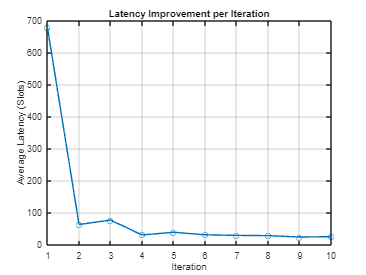

Iteration 1 Timestamp: 01-Jan-2024 16:24:00
Iteration 2 Timestamp: 01-Jan-2024 16:34:35
Iteration 3 Timestamp: 01-Jan-2024 16:47:29
Iteration 4 Timestamp: 01-Jan-2024 16:52:38
Iteration 5 Timestamp: 01-Jan-2024 16:59:10
Iteration 6 Timestamp: 01-Jan-2024 17:04:24
Iteration 7 Timestamp: 01-Jan-2024 17:09:19
Iteration 8 Timestamp: 01-Jan-2024 17:14:07
Iteration 9 Timestamp: 01-Jan-2024 17:18:10
Iteration 10 Timestamp: 01-Jan-2024 17:22:24


  end
        % Update whale positions based on latency
        whalePopulation = UpdateWhalePositionsLT(whalePopulation, whaleProcessingTimes, paramRanges, a, a2);
        % Update the average latency for this iteration
        averageProcessingTimePerIteration(iter) = mean(whaleProcessingTimes);
        fprintf('Latency for iteration %d: %.4f ms\n', iter, mean(whaleProcessingTimes));
        
    end
    
    % Plotting Average Latency per Iteration
    figure;
    plot(1:maxIterations, averageProcessingTimePerIteration, '-o');
    xlabel('Iteration');
    ylabel('Average Latency (ms)');
    title('Latency Improvement per Iteration');
    grid on;
    


## Results

Display the measured throughput. This is calculated as the percentage of the maximum possible throughput of the link given the available resources for data transmission.

% Find and output the best parameter set
[bestLatency, bestIdx] = min(whaleProcessingTimes);
bestWhale = whalePopulation(bestIdx, :);
fprintf('\nLowest Latency: %d ms\n', bestLatency);


Lowest Latency: 1.393848e+01 Slots


fprintf('Best Parameters:\n');

Best Parameters:


disp(bestWhale);

   50.0000   15.0000    0.0000    9.0108



The figure below shows throughput results obtained simulating 10000 subframes (`NFrames = 1000`, `SNRIn = -18:2:16`).

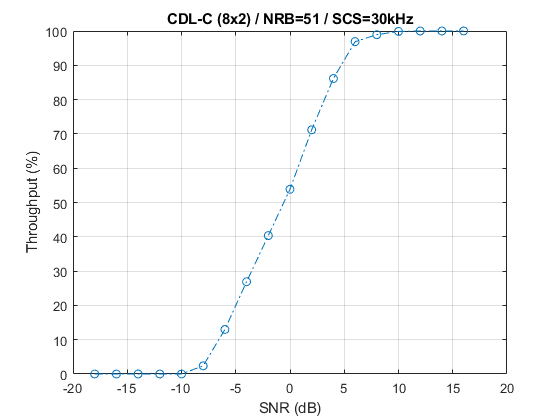

## Selected Bibliography

- 3GPP TS 38.211. "NR; Physical channels and modulation." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.212. "NR; Multiplexing and channel coding." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.213. "NR; Physical layer procedures for control." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.214. "NR; Physical layer procedures for data." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TR 38.901. "Study on channel model for frequencies from 0.5 to 100 GHz." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

## Local Functions

function validateNumLayers(simParameters)
% Validate the number of layers, relative to the antenna geometry

numlayers = simParameters.PDSCH.NumLayers;
ntxants = simParameters.NTxAnts;
nrxants = simParameters.NRxAnts;
antennaDescription = sprintf('min(NTxAnts,NRxAnts) = min(%d,%d) = %d',ntxants,nrxants,min(ntxants,nrxants));
if numlayers > min(ntxants,nrxants)
    error('The number of layers (%d) must satisfy NumLayers <= %s', ...
        numlayers,antennaDescription);
end

% Display a warning if the maximum possible rank of the channel equals
% the number of layers
if (numlayers > 2) && (numlayers == min(ntxants,nrxants))
    warning(['The maximum possible rank of the channel, given by %s, is equal to NumLayers (%d).' ...
        ' This may result in a decoding failure under some channel conditions.' ...
        ' Try decreasing the number of layers or increasing the channel rank' ...
        ' (use more transmit or receive antennas).'],antennaDescription,numlayers); %#ok<SPWRN>
end

end

function estChannelGrid = getInitialChannelEstimate(carrier,nTxAnts,propchannel)
% Obtain channel estimate before first transmission. This can be used to
% obtain a precoding matrix for the first slot.

ofdmInfo = nrOFDMInfo(carrier);

chInfo = info(propchannel);
maxChDelay = ceil(max(chInfo.PathDelays*propchannel.SampleRate)) + chInfo.ChannelFilterDelay;

% Temporary waveform (only needed for the sizes)
tmpWaveform = zeros((ofdmInfo.SampleRate/1000/carrier.SlotsPerSubframe)+maxChDelay,nTxAnts);

% Filter through channel
[~,pathGains,sampleTimes] = propchannel(tmpWaveform);

% Perfect timing synch
pathFilters = getPathFilters(propchannel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);

% Perfect channel estimate
estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

end

function wtx = getPrecodingMatrix(carrier,pdsch,hestGrid,prgbundlesize)
% Calculate precoding matrices for all PRGs in the carrier that overlap
% with the PDSCH allocation

% Maximum CRB addressed by carrier grid
maxCRB = carrier.NStartGrid + carrier.NSizeGrid - 1;

% PRG size
if nargin==4 && ~isempty(prgbundlesize)
    Pd_BWP = prgbundlesize;
else
    Pd_BWP = maxCRB + 1;
end

% PRG numbers (1-based) for each RB in the carrier grid
NPRG = ceil((maxCRB + 1) / Pd_BWP);
prgset = repmat((1:NPRG),Pd_BWP,1);
prgset = prgset(carrier.NStartGrid + (1:carrier.NSizeGrid).');

[~,~,R,P] = size(hestGrid);
wtx = zeros([pdsch.NumLayers P NPRG]);
for i = 1:NPRG
    
    % Subcarrier indices within current PRG and within the PDSCH
    % allocation
    thisPRG = find(prgset==i) - 1;
    thisPRG = intersect(thisPRG,pdsch.PRBSet(:),'rows');
    prgSc = (1:12)' + 12*thisPRG';
    prgSc = prgSc(:);
    
    if (~isempty(prgSc))
        
        % Average channel estimate in PRG
        estAllocGrid = hestGrid(prgSc,:,:,:);
        Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
        
        % SVD decomposition
        [~,~,V] = svd(Hest);
        wtx(:,:,i) = V(:,1:pdsch.NumLayers).';
        
    end
    
end

wtx = wtx / sqrt(pdsch.NumLayers); % Normalize by NumLayers

end

function estChannelGrid = precodeChannelEstimate(carrier,estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate

[K,L,R,P] = size(estChannelGrid);
estChannelGrid = reshape(estChannelGrid,[K*L R P]);
estChannelGrid = hPRGPrecode([K L R P],carrier.NStartGrid,estChannelGrid,reshape(1:numel(estChannelGrid),[K*L R P]),W);
estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end

function plotLayerEVM(NSlots,nslot,pdsch,siz,pdschIndices,pdschSymbols,pdschEq)
% Plot EVM information

persistent slotEVM;
persistent rbEVM
persistent evmPerSlot;

if (nslot==0)
    slotEVM = comm.EVM;
    rbEVM = comm.EVM;
    evmPerSlot = NaN(NSlots,pdsch.NumLayers);
    figure;
end
evmPerSlot(nslot+1,:) = slotEVM(pdschSymbols,pdschEq);
subplot(2,1,1);
plot(0:(NSlots-1),evmPerSlot,'o-');
xlabel('Slot number');
ylabel('EVM (%)');
legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
title('EVM per layer per slot');

subplot(2,1,2);
[k,~,p] = ind2sub(siz,pdschIndices);
rbsubs = floor((k-1) / 12);
NRB = siz(1) / 12;
evmPerRB = NaN(NRB,pdsch.NumLayers);
for nu = 1:pdsch.NumLayers
    for rb = unique(rbsubs).'
        this = (rbsubs==rb & p==nu);
        evmPerRB(rb+1,nu) = rbEVM(pdschSymbols(this),pdschEq(this));
    end
end
plot(0:(NRB-1),evmPerRB,'x-');
xlabel('Resource block');
ylabel('EVM (%)');
legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
title(['EVM per layer per resource block, slot #' num2str(nslot)]);

drawnow;

end

*Copyright 2017-2022 The MathWorks, Inc.*